clearvars;
close all;

[y, Fs] = audioread('Tomppabeats - Blossom Samurai (Official Audio).mp4');

% Del 1: FUL(fas)vocoder %
audiofile_w_song = y(20*Fs:50*Fs, 1); % Med sång (Är mono redan?)

% ---- Ändring av tonhöjd utan att ändra tempo ---- % KLAR!
pitch = 0.9; % 0.9 är 10% lägre pitch än originalet, 1.5 är 50% högre pitch
speed = 1.0; % Uppspelningshastigheten
newSpeed = speed/pitch; % Fixa uppspelningshastigheten

if pitch == 1
    Fs2 = Fs; 
else
    Fs2 = Fs * pitch;
end 

% --- Variabler --- %
windowSize = Fs*0.05; % 5% av samplingsfrekvensen = 2205 sampels, måste vara ett heltal
stepSize = round(newSpeed * windowSize); % Måste vara ett heltal

% ---- Indexarray ---- % 
newFrame = zeros(round(length(audiofile_w_song) * (windowSize / stepSize) + windowSize), 1); % Indexarray med längden av originalljudet samt lite marginal
k = 1;

for i = (0:stepSize:length(audiofile_w_song)-1)
    for j = (0:(windowSize-1))
        newFrame(k) =  i + j + 1;
        k = k + 1;
    end
end

ix = (newFrame > 0) & (newFrame < length(audiofile_w_song)); % Array med booleans 
newFrame = newFrame(ix);

phaseVocodedSound = audiofile_w_song(newFrame); % Läser sampels

% ---- Uppspelning ---- %
ogObj = audioplayer(audiofile_w_song, Fs);
songPhaseObj = audioplayer(phaseVocodedSound, Fs2);

%play(songPhaseObj)
%play(ogObj)
stop(songPhaseObj)
%stop(ogObj)

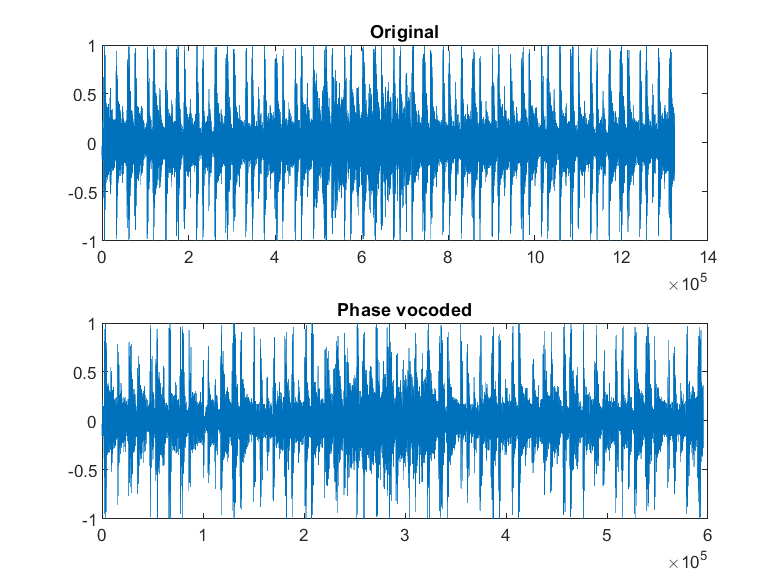

% ---- Plotta figurer för jämförelse ---- %
figure;
subplot(211)
plot(audiofile_w_song)
title('Original')
subplot(212)
plot(phaseVocodedSound)
title('Phase vocoded')